clear all
clf
%Tressider Errors From Ground Truth
%Change
muBarTressiderC=.21265;
sigBarTressiderC=.36459;
muGPSTressiderC=3.6753;
sigGPSTressiderC=13.2658;
%Absolute
muBarTressiderABS=.21437;
sigBarTressiderABS=.3637;
muGPSTressiderABS=23.4656;
sigGPSTressiderABS=8.7439;
%Constants
sigGPSTressiderTheo=39.35;
cn0Tressider="33";


%Spiral Errors From Ground Truth
%Change
muBarSpiralC=.76463;
sigBarSpiralC=.41445;
muGPSSpiralC=-2.9532;
sigGPSSpiralC=25.2643;
%Absolute
muBarSpiralABS=.78446;
sigBarSpiralABS=.41126;
muGPSSpiralABS=11.6217;
sigGPSSpiralABS=8.2450;
%Constants
sigGPSSpiralTheo=135.46;
cn0Spiral="26.95";

%Inside Errors From Ground Truth
%Change
muBarInsideC=0.04099;
sigBarInsideC=.15988;
muGPSInsideC=-29.5726;
sigGPSInsideC=102.467;
%Absolute
muBarInsideABS=.06071;
sigBarInsideABS=.15599;
muGPSInsideABS=.9413;
sigGPSInsideABS=87.96;
%Constants
cn0Inside="22.15";
sigGPSInsideTheo=676.507;

%plots
disp("Tressider")

Tressider


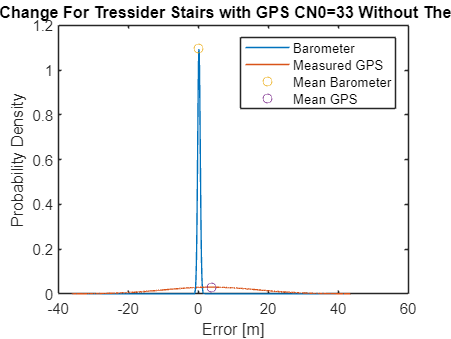

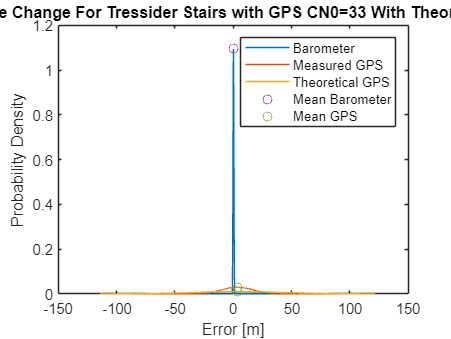

getPlots(muBarTressiderC,sigBarTressiderC,muGPSTressiderC,sigGPSTressiderC,sigGPSTressiderTheo,1000,"Error In Altitude Change For Tressider Stairs with GPS CN0="+cn0Tressider)

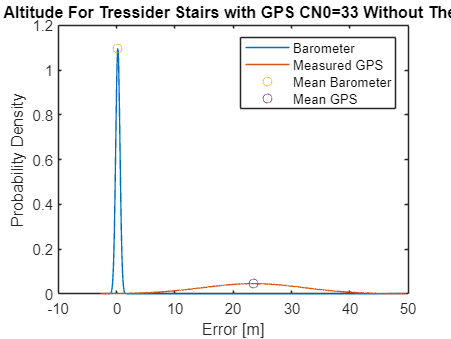

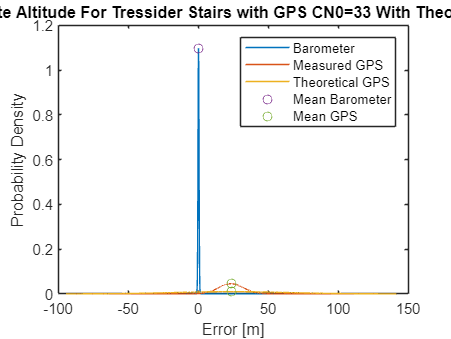

getPlots(muBarTressiderABS,sigBarTressiderABS,muGPSTressiderABS,sigGPSTressiderABS,sigGPSTressiderTheo,2000,"Error In Absolute Altitude For Tressider Stairs with GPS CN0="+cn0Tressider)

disp("Spiral")

Spiral


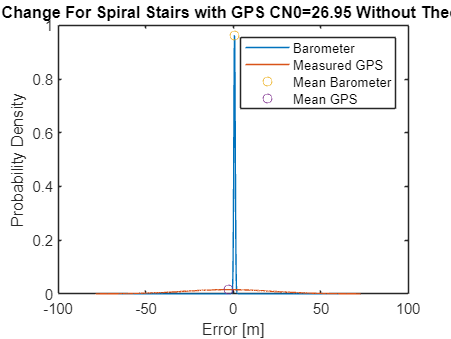

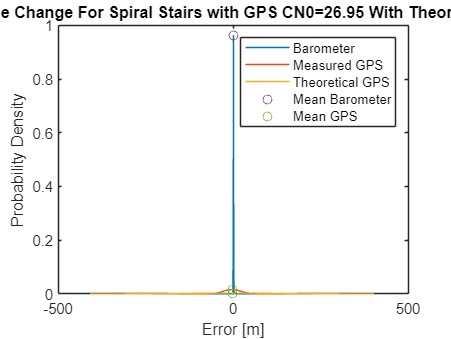

getPlots(muBarSpiralC,sigBarSpiralC,muGPSSpiralC,sigGPSSpiralC,sigGPSSpiralTheo,3000,"Error In Altitude Change For Spiral Stairs with GPS CN0="+cn0Spiral)

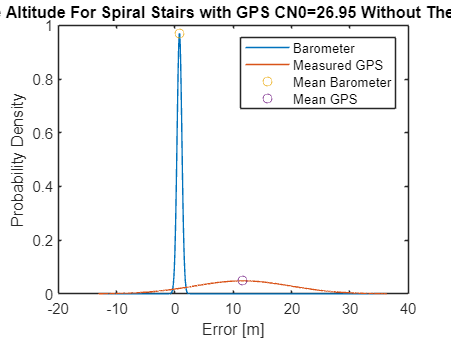

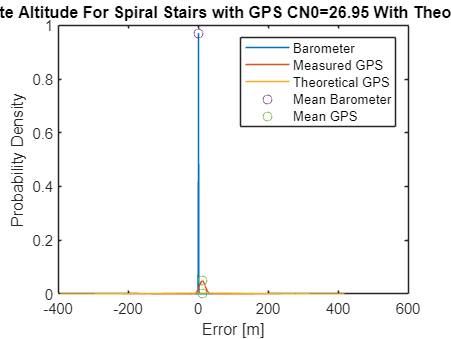

getPlots(muBarSpiralABS,sigBarSpiralABS,muGPSSpiralABS,sigGPSSpiralABS,sigGPSSpiralTheo,4000,"Error In Absolute Altitude For Spiral Stairs with GPS CN0="+cn0Spiral)

disp("Inside")

Inside


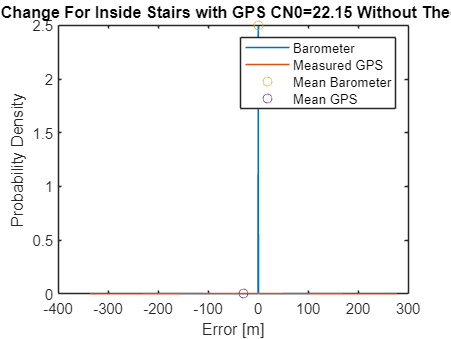

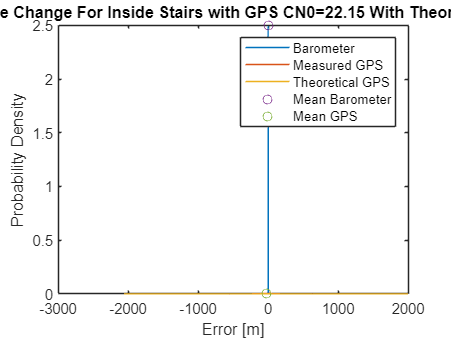

getPlots(muBarInsideC,sigBarInsideC,muGPSInsideC,sigGPSInsideC,sigGPSInsideTheo,5000,"Error In Altitude Change For Inside Stairs with GPS CN0="+cn0Inside)

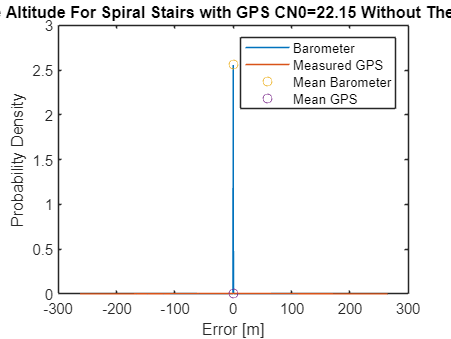

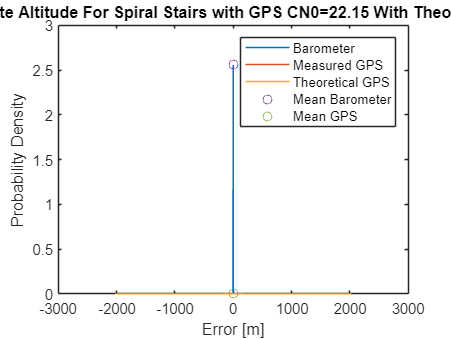

getPlots(muBarInsideABS,sigBarInsideABS,muGPSInsideABS,sigGPSInsideABS,sigGPSInsideTheo,6000,"Error In Absolute Altitude For Spiral Stairs with GPS CN0="+cn0Inside)

function getPlots(muBar,sigBar,muGPS,sigGPS,sigTheo,figNum,titleStr)
    xval1=[min(-3*sigBar+muBar,-3*sigGPS+muGPS):.01:max(3*sigBar+muBar,3*sigGPS+muGPS)];
    xval2=[min([-3*sigBar+muBar,-3*sigGPS+muGPS,-3*sigTheo+muGPS]):.01:max([3*sigBar+muBar,3*sigGPS+muGPS,3*sigTheo+muGPS])];
    barY1=normpdf(xval1,muBar,sigBar);
    gpsY1=normpdf(xval1,muGPS,sigGPS);
    barY2=normpdf(xval2,muBar,sigBar);
    gpsY2=normpdf(xval2,muGPS,sigGPS);
    theoY2=normpdf(xval2,muGPS,sigTheo);
    figure(figNum)
    plot(xval1,barY1)
    hold on
    plot(xval1,gpsY1)
    ylabel("Probability Density")
    xlabel("Error [m]")
    title(titleStr+" Without Theorhetical GPS STD")
    scatter(muBar,normpdf(muBar,muBar,sigBar))
    scatter(muGPS,normpdf(muGPS,muGPS,sigGPS))
    legend("Barometer","Measured GPS","Mean Barometer","Mean GPS")
    hold off
    figure(figNum+1)
    plot(xval2,barY2)
    hold on
    plot(xval2,gpsY2)
    plot(xval2,theoY2)
    ylabel("Probability Density")
    xlabel("Error [m]")
    title(titleStr+" With Theorhetical GPS STD")
    scatter(muBar,normpdf(muBar,muBar,sigBar))
    scatter([muGPS,muGPS],[normpdf(muGPS,muGPS,sigGPS),normpdf(muGPS,muGPS,sigTheo)])
    legend("Barometer","Measured GPS","Theoretical GPS","Mean Barometer","Mean GPS")
    hold off
end